% Second order transfer function with Zeta = 1 or Zeta = 0

## STEP -1 : Make a 2nd order Transfer Function

%Recall the generic form of the second order transfer function
% H(s) = wn^2/(s^2 + 2*zeta*wn*s + wn^2)
%For illsutration let us assume 
wn = 2; % Any value > 0 can be taken 
%-- Now based on zeta there are different cases. We consider the case with
% CASE  zeta  = 1

## Step 1 For example, zeta = 1

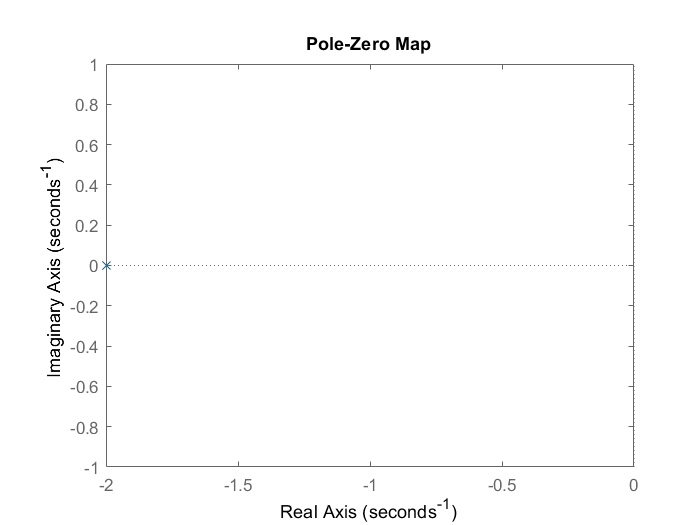

zeta_a = 1;
NUM_a = wn*wn; DEN_a = [1 2*zeta_a*wn wn*wn];
H_a = tf(NUM_a,DEN_a);
P_a = pole(H_a);
Z_a = zero(H_a); 
%-- Pole zero plot
figure; pzplot(H_a);

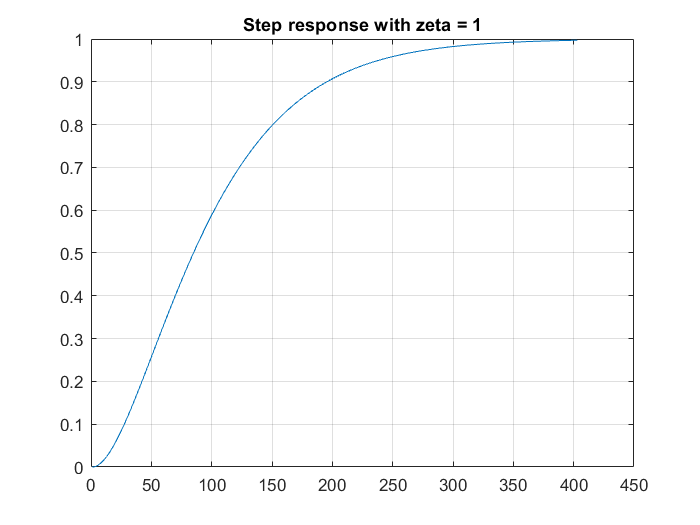

% Response to step input
H1_step = step(H_a);
figure; plot(H1_step);grid on;
title('Step response with zeta = 1');

## Step 2 Influence of zeta = 0

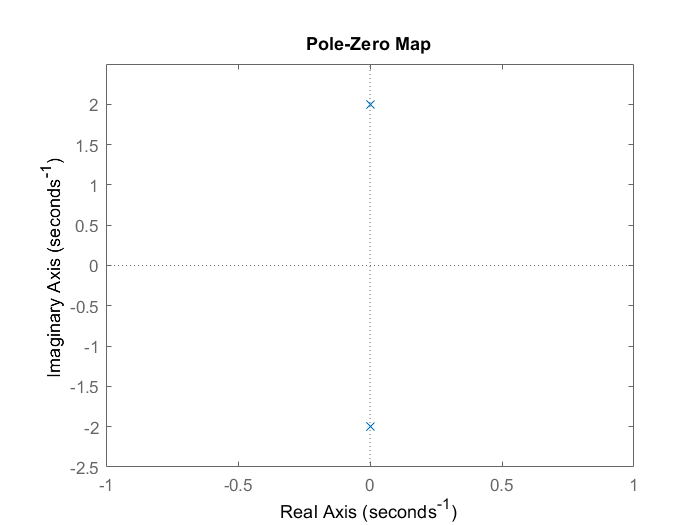

zeta_a = 0;
NUM_a = wn*wn; DEN_a = [1 2*zeta_a*wn wn*wn];
H_a = tf(NUM_a,DEN_a);
P_a = pole(H_a);
Z_a = zero(H_a); 
%-- Pole zero plot
figure; pzplot(H_a);

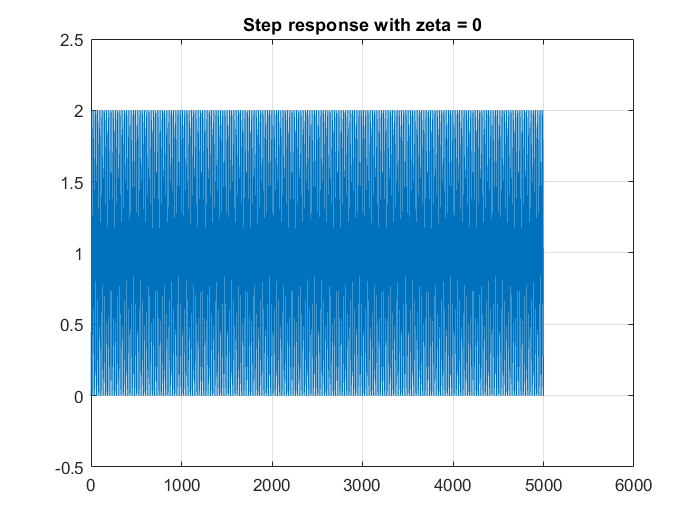

% Response to step input
H1_step = step(H_a);
figure; plot(H1_step);grid on;
title('Step response with zeta = 0');